# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;
storeFigures = true; % set true if you want to save plots

## Problem 1:

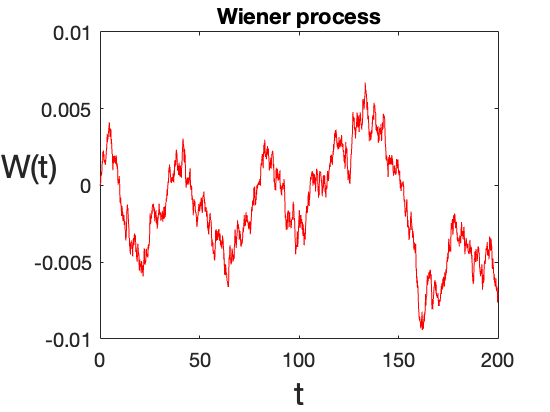

% Y(s) = 1/(1+s*tau)^2 *(U(s)+D(s))
% Find continusous-time stochastic state space model
% Create disturbance as a Wiener process
% Intensity of disturbance Q = 0.001

Qc  = 0.001;
Rc  = 0.01*0.01;
n_seconds = 200;

% Solution
% Continuous-time system

% Wiener Process 
N = 2000; % 1000
dt = n_seconds/N;

dW = zeros(1,N);                
W = zeros(1,N);                 
dW(1) = Qc*sqrt(dt)*randn();    
W(1) = dW(1);                  
for j = 2:N
    dW(j)= Qc*sqrt(dt)*randn();
    W(j) = W(j-1) + dW(j);
end
figure(1);
plot([0:dt:n_seconds],[0,W],'r-')     
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");

% mean and variance
MeanWiener = mean(W)

MeanWiener = -0.0014

VarianceWiener = var(W)

VarianceWiener = 1.0595e-05

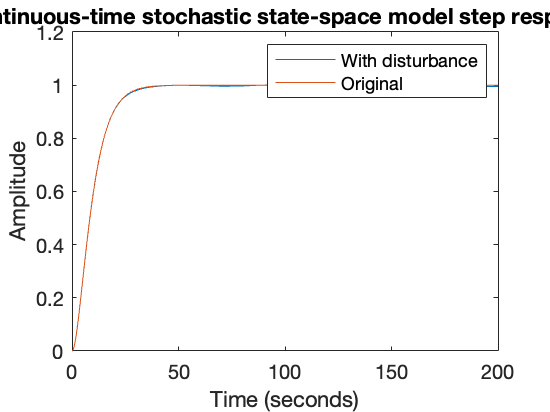



tau = 50*dt; % 50 seconds
sys = tf(1,[tau^2 2*tau 1]);
step_input = ones(1,N+1);
disturbance = [0,W];
response = lsim(sys,step_input+disturbance,[0:dt:n_seconds]);
response_original = lsim(sys,step_input,[0:dt:n_seconds]);

figure(2);
plot([0:dt:n_seconds],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Continuous-time stochastic state-space model step response");
hold on
plot([0:dt:n_seconds],response_original);
legend("With disturbance","Original");

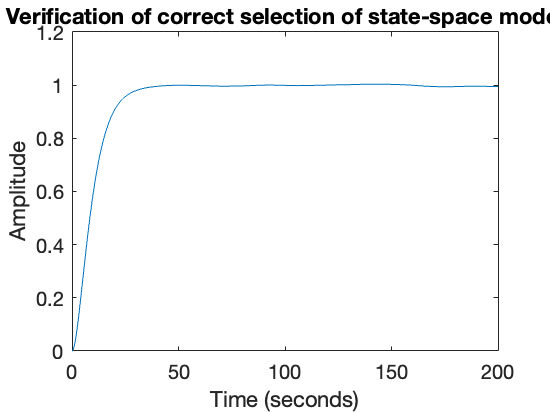

legend show
fix_ylim = ylim;

% . 
% x = Ax + Bu + Gw      {State equation}
% y = Cx + Du +  v      {Measurements}

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
B = [B G];
D = [D 0];
sys = ss(A,B,C,D);
step_input = ones(1,N+1);
disturbance = [0,W];
%% verification of stochastic state space model derivation
response = lsim(sys,[step_input;disturbance],[0:dt:n_seconds]);
figure(3);
plot([0:dt:n_seconds],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Verification of correct selection of state-space model");

## Problem 2:

% Find discrete-time model
% Find Kalman filter
% Ts = 20s
% Evaluate predicted and filtered values
Ts = 20;
dsys = c2d(sys,Ts,'tustin');
Qn = Qc*eye(2);
Rn = Rc*eye(1);
[kest,L,P,M,Z] = kalman(dsys,Qn,Rn);
P % minimal prediction co-variance  P(t|t-1)

P =     0.0435    0.0450
    0.0450    0.3354


Z % minimal filtering co-variance   P(t|t)

Z =     0.0332    0.0118
    0.0118    0.2284


## Problem 3:

% Find Kalman Filter models
% Use asynchronous sampling with controller computation time
% Tc = 10/1/0.1/s
% Compare properties of noise models
% Evaluate P (predicted value)

Ts = 20;
Tcs = [10 1 0.1];
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    funB = @(x) expm(A.*x);
    funD = @(x) expm(A.*x);
    funQ = @(x) Qc*expm(A.*x)*expm(A'.*x);
    funS = @(x) Qc*expm(A.*x)*expm(A'*x)*C';
    funR = @(x) Qc*C*expm(A.*x)*expm(A'.*x)*C';

    Aasync = expm(A.*Ts);
    Casync = C*expm(A.*etta*Ts);
    Basync = integral(funB,0,Ts,'ArrayValued', true);
    Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
    Q = integral(funQ,0,Ts,'ArrayValued', true);
    S = integral(funS,0,etta*Ts,'ArrayValued', true);
    R = integral(funR,0,etta*Ts,'ArrayValued', true);
    Basync = Basync*B;
    Dasync = C*Dasync*B;
    R = Rc + R;

    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Tcs(i)),Q,R,S);
    P
    Z

end

Tc


    10



P =     0.0002    0.0051
    0.0051    0.1986


Z =     0.0002    0.0051
    0.0051    0.1978


Tc


     1



P =     0.0000    0.0010
    0.0010    0.0606


Z =     0.0000    0.0010
    0.0010    0.0606


Tc


    0.1000



P =     0.0000    0.0009
    0.0009    0.0586


Z =     0.0000    0.0009
    0.0009    0.0586


## Problem 4:

% Show impact of neglecting S in case of asynchronous sampling
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;

    funB = @(x) expm(A.*x);
    funD = @(x) expm(A.*x);
    funQ = @(x) Qc.*expm(A.*x)*expm(A'.*x);
    funS = @(x) Qc.*expm(A.*x)*expm(A'.*x)*C';
    funR = @(x) Qc.*C*expm(A.*x)*expm(A'.*x)*C';

    Aasync = expm(A*Ts);
    Casync = C*expm(A*etta*Ts);
    Basync = integral(funB,0,Ts,'ArrayValued', true);
    Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
    Q = integral(funQ,0,Ts,'ArrayValued', true);
    S = integral(funS,0,etta*Ts,'ArrayValued', true);
    R = integral(funR,0,etta*Ts,'ArrayValued', true);
    Basync = Basync*B;
    Dasync = C*Dasync*B;
    R = Rc + R;

    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    disp("With S")
    P
    Z
    disp("Value of determinant with S")
    disp(det(P))
    disp("With S=0")
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R);
    P
    Z
    disp("Value of determinant without S")
    det(P)
end

Tc


    10



With S


P =     0.0002    0.0051
    0.0051    0.1986


Z =     0.0002    0.0051
    0.0051    0.1978


Value of determinant with S


   8.8138e-06



With S=0


P =     0.0003    0.0082
    0.0082    0.3125


Z =     0.0003    0.0081
    0.0081    0.3102


Value of determinant without S


ans = 2.0777e-05

Tc


     1



With S


P =     0.0000    0.0010
    0.0010    0.0606


Z =     0.0000    0.0010
    0.0010    0.0606


Value of determinant with S


   1.0796e-06



With S=0


P =     0.0001    0.0017
    0.0017    0.1024


Z =     0.0001    0.0017
    0.0017    0.1024


Value of determinant without S


ans = 3.0882e-06

Tc


    0.1000



With S


P =     0.0000    0.0009
    0.0009    0.0586


Z =     0.0000    0.0009
    0.0009    0.0586


Value of determinant with S


   1.0099e-06



With S=0


P =     0.0001    0.0016
    0.0016    0.0993


Z =     0.0001    0.0016
    0.0016    0.0993


Value of determinant without S


ans = 2.9005e-06

%% Conclusion: inclusion of S decreases the values of covariances

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with decorrelated noise
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;

funB = @(x) expm(A.*x);
funD = @(x) expm(A.*x);
funQ = @(x) Qc.*expm(A.*x)*expm(A'.*x);
funS = @(x) Qc.*expm(A.*x)*expm(A'.*x)*C';
funR = @(x) Qc.*C*expm(A.*x)*expm(A'.*x)*C';

Aasync = expm(A*Ts);
Casync = C*expm(A*etta*Ts);
Basync = integral(funB,0,Ts,'ArrayValued', true);
Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
Q = integral(funQ,0,Ts,'ArrayValued', true);
S = integral(funS,0,etta*Ts,'ArrayValued', true);
R = integral(funR,0,etta*Ts,'ArrayValued', true);
Basync = Basync*B;
Dasync = C*Dasync*B;
R = Rc + R;

A_decor = Aasync - S*inv(R)*Casync;
B_decor = Basync - S*inv(R)*Dasync;
Q_decor = Q - S*inv(R)*S';

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

State covariance matrix P(t|t) for system model with decorrelated noise



[kest,L,P,M,Z] = kalman(ss(A_decor,B_decor,C,D,Ts),Q_decor,R);
Tc

Tc = 0.1000

P

P =     0.0052    0.1588
    0.1588    4.8939


Z

Z =     0.0001    0.0032
    0.0032    0.0975


det(Z)

ans = 3.1197e-06

## Additional tools

% % Storing figures
% if storeFigures
%     for i=1:10
%         filename = strcat('figure_',num2str(i));
%         foldername = './figures/';
%         saveas(figure(i),fullfile(foldername,filename),'jpg');
%     end
% end